## continuous

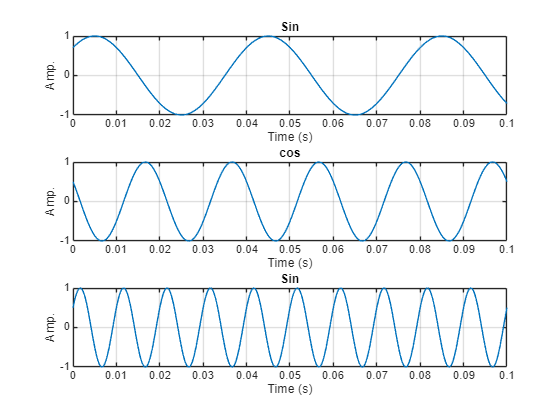

clear; clc; close all;
t = linspace(0,0.1,1001);

Freq1 = 25;
%phase = (degree * pi) / 180;
phase1 = (45 * pi) / 180;
Freq2 = 50;
%phase = (degree * pi) / 180;
phase2 = (60 * pi) / 180;
Freq3 = 100;
%phase = (degree * pi) / 180;
phase3 = (30 * pi) / 180;

x1t = sin(2*pi*Freq1*t + phase1);
x2t = cos(2*pi*Freq2*t + phase2);
x3t = sin(2*pi*Freq3*t + phase3);

figure(1);
subplot(3,1,1);
plot(t,x1t);
xlabel('Time (s)')
ylabel('Amp.')
title('Sin')
grid on

subplot(3,1,2);
plot(t,x2t);
xlabel('Time (s)')
ylabel('Amp.')
title('cos')
grid on

subplot(3,1,3);
plot(t,x3t);
xlabel('Time (s)')
ylabel('Amp.')
title('Sin')
grid on

## discreate

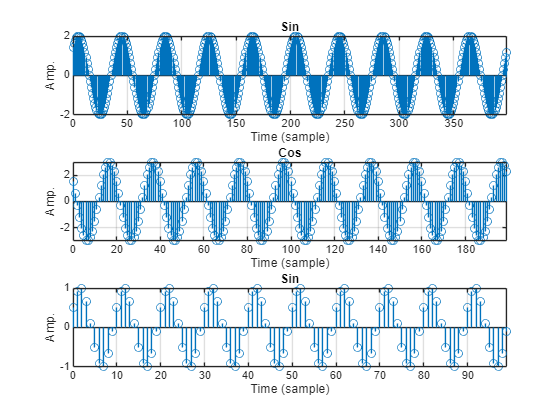

samp= 1000;

n1 = 0:399;
n2 = 0:199;
n3 = 0:99;
f1 = Freq1/samp; % <-- sample^-1
f2 = Freq2/samp; % <-- sample^-1
f3 = Freq3/samp; % <-- sample^-1
%phase = (degree * pi) / 180;
x1n = 2*sin(2*pi*f1*n1 + phase1); 
x2n = 3*cos(2*pi*f2*n2 + phase2);
x3n = sin(2*pi*f3*n3 + phase3); 
% angular freq = 2*pi*f1 (rad/sample)

figure(2);
subplot(3,1,1);
stem(n1,x1n);
xlim([0 max(n1)]);
xlabel('Time (sample)')
ylabel('Amp.')
title('Sin')
grid on

subplot(3,1,2);
stem(n2,x2n);
xlim([0 max(n2)]);
xlabel('Time (sample)')
ylabel('Amp.')
title('Cos')
grid on

subplot(3,1,3);
stem(n3,x3n);
xlim([0 max(n3)]);
xlabel('Time (sample)')
ylabel('Amp.')
title('Sin')
grid on

## Digital filter

% make low pass filter : w0 = 0 rad/sample.
% low pass filter sinc func. : hd[n] = sinc(nwc)/(n*pi)
% for make other  hd[n] = (sinc(nwc)/(n*pi)) * cos(nw0)
% not calculate only n = 0 , we just use l'hospital rule. hd[n=0] = wc/pi
% look at angular freq.
% w1 = 2*pi*f1 , w2 = 2*pi*f2 , w3 = 2*pi*f3

w1 = 2*pi*f1;
w2 = 2*pi*f2;
w3 = 2*pi*f3;

wc = (3*pi) / 40;
M  = 10;
L  = 2*M + 1; % <- 21 sample 
n  = -M:M; % -10:10 even func.
hLP = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hLP(x) = wc/pi;
    else
        hLP(x) = sin(wc*n(x)) / (pi*n(x));
    end
end

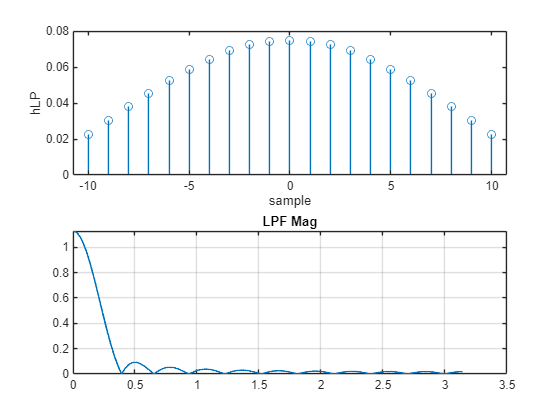

w = linspace(0, pi, 1001);
HLP = 0;

for i = 1:length(hLP)
    HLP = HLP  + hLP(i) * exp(-1i*w*n(i));
end

figure(3);
subplot(2,1,1);
stem(n,hLP);
xlabel('sample');
ylabel('hLP');
subplot(2,1,2);
plot(w, abs(HLP), 'LineWidth', 1.2); grid on;
title('LPF Mag');

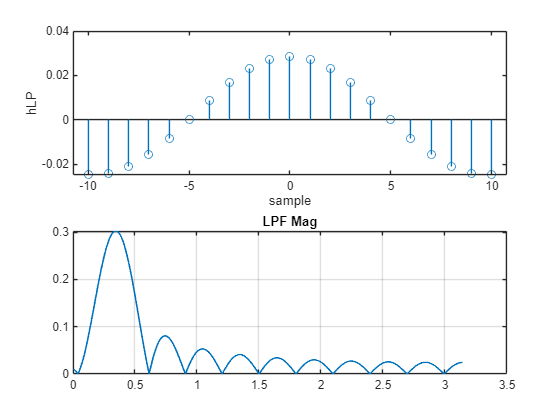


% cut w1,w3
% pass w2
w0 = pi / 10;
wc = pi / 35;
hd = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hd(x) = wc/pi;
    else
        hd(x) = (sin(wc*n(x)) / (pi*n(x))) * cos(w0*n(x));
    end
end
Hd = 0;
for i = 1:length(hd)
    Hd = Hd  + hd(i) * exp(-1i*w*n(i));
end
figure(4);
subplot(2,1,1);
stem(n,hd);
xlabel('sample');
ylabel('hLP');
subplot(2,1,2);
plot(w, abs(Hd), 'LineWidth', 1.2); grid on;
title('LPF Mag');

## convolution

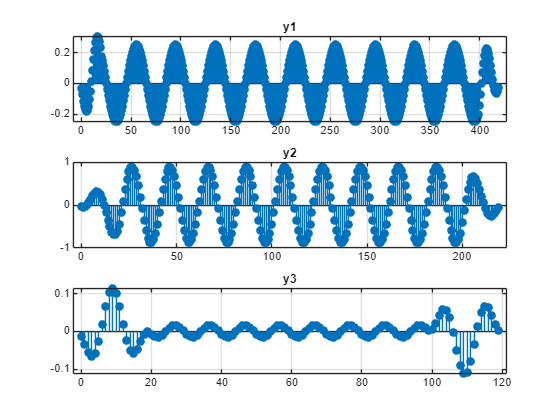

% band pass x2t 
y1 = 0;
y2 = 0;
y3 = 0;

Nx1 = length(x1n);
Nx2 = length(x2n);
Nx3 = length(x3n);
Nh  = length(hd);

Ny1 = Nx1 + Nh - 1;
Ny2 = Nx2 + Nh - 1;
Ny3 = Nx3 + Nh - 1;

y1 = zeros(1, Ny1);
y2 = zeros(1, Ny2);
y3 = zeros(1, Ny3);

for n = 0:Ny1-1
    for k = 0:Nh-1
        if (n-k >= 0) && (n-k < Nx1)
            y1(n+1) = y1(n+1) + x1n(n-k+1)*hd(k+1);
        end
    end
end

for n = 0:Ny2-1
    for k = 0:Nh-1
        if (n-k >= 0) && (n-k < Nx2)
            y2(n+1) = y2(n+1) + x2n(n-k+1)*hd(k+1);
        end
    end
end

for n = 0:Ny3-1
    for k = 0:Nh-1
        if (n-k >= 0) && (n-k < Nx3)
            y3(n+1) = y3(n+1) + x3n(n-k+1)*hd(k+1);
        end
    end
end

figure(5);
subplot(3,1,1);
n1y = 0:Ny1-1;
stem(n1y, y1, 'filled'); grid on;
title("y1");

subplot(3,1,2);
n2y = 0:Ny2-1;
stem(n2y, y2, 'filled'); grid on;
title("y2");

subplot(3,1,3);
n3y = 0:Ny3-1;
stem(n3y, y3, 'filled'); grid on;
title("y3");

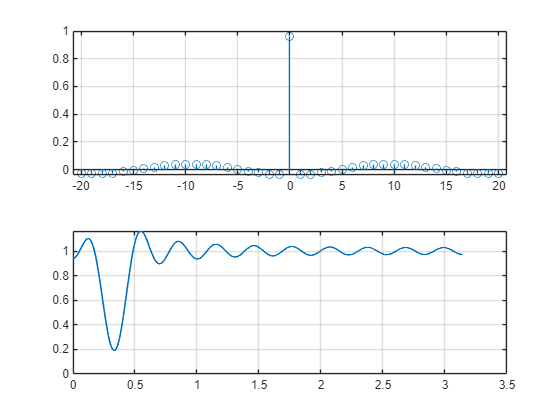


% BRF
fs = samp;                 
w1 = 2*pi*(Freq1/fs);     
w2 = 2*pi*(Freq2/fs);      
w3 = 2*pi*(Freq3/fs);      

w_stop1 = pi/12;           
w_stop2 = pi/8;            

M  = 20;
L  = 2*M + 1;
n  = -M:M;

hLP1 = zeros(1,L);
hLP2 = zeros(1,L);

for i = 1:L
    if n(i) == 0
        hLP1(i) = w_stop1/pi;
        hLP2(i) = w_stop2/pi;
    else
        hLP1(i) = sin(w_stop1*n(i)) / (pi*n(i));
        hLP2(i) = sin(w_stop2*n(i)) / (pi*n(i));
    end
end

hBP = hLP2 - hLP1;

delta = zeros(1,L);
delta(M+1) = 1;

hBR = delta - hBP;

w = linspace(0, pi, 1001);
HBR = 0;
for i = 1:L
    HBR = HBR + hBR(i) * exp(-1i*w*n(i));
end

figure(6);
subplot(2,1,1);
stem(n, hBR); grid on;

subplot(2,1,2);
plot(w, abs(HBR), 'LineWidth', 1.2); grid on;

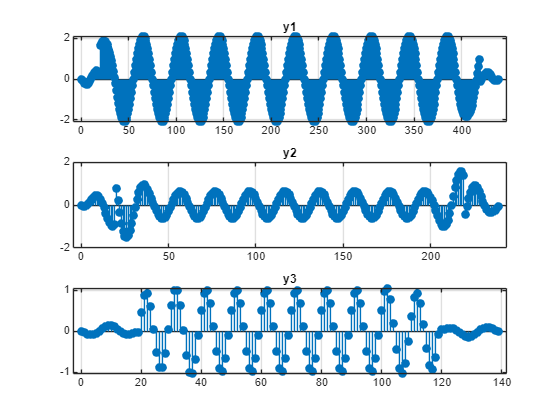

y1 = 0; y2 = 0; y3 = 0;

Nx1 = length(x1n);
Nx2 = length(x2n);
Nx3 = length(x3n);
Nh  = length(hBR);        

Ny1 = Nx1 + Nh - 1;
Ny2 = Nx2 + Nh - 1;
Ny3 = Nx3 + Nh - 1;

y1 = zeros(1, Ny1);
y2 = zeros(1, Ny2);
y3 = zeros(1, Ny3);

for nn = 0:Ny1-1
    for k = 0:Nh-1
        if (nn-k >= 0) && (nn-k < Nx1)
            y1(nn+1) = y1(nn+1) + x1n(nn-k+1)*hBR(k+1);
        end
    end
end

for nn = 0:Ny2-1
    for k = 0:Nh-1
        if (nn-k >= 0) && (nn-k < Nx2)
            y2(nn+1) = y2(nn+1) + x2n(nn-k+1)*hBR(k+1);
        end
    end
end

for nn = 0:Ny3-1
    for k = 0:Nh-1
        if (nn-k >= 0) && (nn-k < Nx3)
            y3(nn+1) = y3(nn+1) + x3n(nn-k+1)*hBR(k+1);
        end
    end
end

figure;
subplot(3,1,1); stem(0:Ny1-1, y1, 'filled'); grid on; title('y1');
subplot(3,1,2); stem(0:Ny2-1, y2, 'filled'); grid on; title('y2');
subplot(3,1,3); stem(0:Ny3-1, y3, 'filled'); grid on; title('y3');